# Example 3.20: Realizations in the 95% Ellipse

Note: this script completes Example 3.20 (Section 3.8.5) of **Statistics for Chemical Engineers**: it counts how many realizations fall inside the 95% confidence ellipse. Victor Z UW-Madison, 2019 samples of multivariate Gaussian lie on ellipse

clc; clear all; close all hidden; format short;

addpath('./Support')

## Model

specify mean and covariance

mu = [0 0];
Sigma = [1 -0.5; -0.5 1]; % anticorrelated

% compute the 95% confidence interval ellipse
alpha = 0.95; % confidence 
n = 2; % dimension of variable
A = inv(Sigma); % inverse covariance
b = chi2inv(alpha, n); % confidence level on 2d from chi2 distribution
[xe, ye, major, minor, bbox] = ellipse(A, b, 100, mu); % ellipse

## Fraction inside the ellipse

count the number of samples in the ellipse

rng(0)
nsample = 1000; % number of random samples
sample = mvnrnd(mu,Sigma,nsample); % collect samples

## Plot

plot the ellipse and the samples

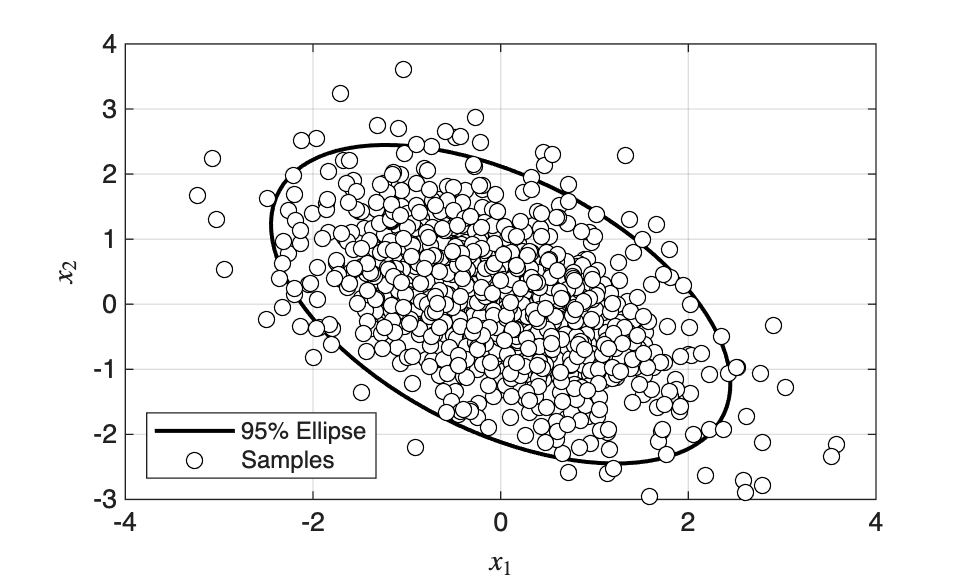

figure(1); 
plot(xe,ye,'k','LineWidth',1.5) % plot ellipse
hold on;
plot(sample(:,1),sample(:,2),'blacko','MarkerFaceColor','w'); % plot samples
xlabel('$x_1$','Interpreter','latex'); ylabel('$x_2$','Interpreter','latex');
legend('95% Ellipse','Samples','location','southwest')
grid on
print -depsc ch3_gaussian_ellipsoid_points.eps


cnt = 0;
for i=1:nsample
    x = sample(i,:)-mu;
    if x*inv(Sigma)*x'<=b % count if in the confidence interval
        cnt=cnt+1;
    end        
end
fprintf('%i among %i samples in the ellipse\n',cnt,nsample); % print the result

942 among 1000 samples in the ellipse


## Note

As in the book, the fraction of realizations inside the ellipse converges to 95% as the number of realizations grows.